## Image segmentation using region growing

%img="new/mdb001.tiff";

%put images file location here

%use absolute path to indicate file location
breastImds=imageDatastore( ...
    "C:\Users\Daniel Kee\Documents\Monash\FYP\FIT3162\fit3162\Code\MIAS(no muscle)");

%add more condition 
condition = ['B';'B';'N';'N';'B';'B';'N';'N';'N';'N';'B';'N';'B';'B';'N';'B';...
    'N';'B';'N';'B';'N';'B';'N';'M';'N';'B';'N';'N';'M';'N';'B';'N';'B';'N';...
    'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';...
    'N';'N';'N';'N';'N';'N';'M';'B';'N';'N';'N';'B';'N';'N';'N';'N';'N';'B';...
    'N';'N';'M';'N';'N';'M';'N';'N';'N';'N';'B';'B';'N';'B';'N';'N';'N';'N';...
    'N';'N';'M';'B';'M';'N';'N';'M';'N';'B';'N';'B';'N';'N';'M';'N';'B';'M';...
    'N';'B';'N';'N';'M';'M';'N';'N';'N';'M';'N';'M';'N';'N';'M';'B';'N';'N';...
    'M';'M';'B';'B';'N';'N';'M';'N';'B';'B';'N';'M';'N';'N';'N';'N';'N';'N';...
    'M';'B';'N';'B';'M';'B';'N';'N';'M';'N';'B';'N';'B';'N';'N';'M';'N';'N';...
    'M';'N';'B';'N';'N';'B';'N';'B';'N';'B';'N';'N';'M';'M';'N';'N';'N';'B';...
    'N';'N';'M';'M';'N';'M';'N';'N';'M';'N';'M';'N';'B';'N';'B';'B';'N';'B';...
    'N';'B';'N';'N';'B';'B';'N';'N';'M';'N';'B';'N';'M';'B';'N';'M';'N';'M';...
    'B';'M';'B';'N';'M';'N';'B';'B';'N';'N';'B';'B';'B';'N';'N';'B';'B';'B';...
    'B';'N';'N';'N';'M';'N';'M';'N';'N';'B';'N';'M';'M';'M';'B';'M';'N';'N';...
    'B';'M';'N';'N';'B';'M';'M';'N';'N';'B';'M';'N';'N';'M';'N';'N';'N';'N';...
    'N';'N';'N';'M';'M';'N';'M';'N';'N';'M';'M';'N';'N';'M';'N';'N';'N';'N';...
    'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'B';'N';'N';'N';'N';'N';'N';...
    'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'N';'B';'N';'B';...
    'B';'N';'N';'N';'N';'N';'N';'N']

condition = 330×1 char array
    'B'
    'B'
    'N'
    'N'
    'B'
    'B'
    'N'
    'N'
    'N'
    'N'
    'B'
    'N'
    'B'
    'B'
    'N'
    'B'
    'N'
    'B'
    'N'
    'B'
    'N'
    'B'
    'N'
    'M'
    'N'
    'B'
    'N'
    'N'
    'M'
    'N'
    'B'
    'N'
    'B'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'M'
    'B'
    'N'
    'N'
    'N'
    'B'
    'N'
    'N'
    'N'
    'N'
    'N'
    'B'
    'N'
    'N'
    'M'
    'N'
    'N'
    'M'
    'N'
    'N'
    'N'
    'N'
    'B'
    'B'
    'N'
    'B'
    'N'
    'N'
    'N'
    'N'
    'N'
    'N'
    'M'
    'B'
    'M'
    'N'
    'N'
    'M'
    'N'
    'B'
    'N'
    'B'
    'N'
    'N'
    'M'
    'N'
    'B'
    'M'
    'N'
    'B'
    'N'
    'N'
    'M'
    'M'
    'N'
    'N'
    'N'
    'M'
    'N'
    'M'
    'N'
    'N'
    'M'
   

Optimization terminated: maximum number of generations exceeded.


seuil =      1    41   125   255


     1841422        2280
        2280      247076



       Contrast: 0.0022
    Correlation: 0.9896
         Energy: 0.7879
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil =      1    41   111   173   255


     1900396        2335
        2335      187992



       Contrast: 0.0022
    Correlation: 0.9865
         Energy: 0.8324
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil =      1    66   167   255


     1819334        2702
        2702      268320



       Contrast: 0.0026
    Correlation: 0.9885
         Energy: 0.7720
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1092524        5426
        5426      989682



       Contrast: 0.0052
    Correlation: 0.9896
         Energy: 0.4960
    Homogeneity: 0.9974



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1029430        3364
        3364     1056900



       Contrast: 0.0032
    Correlation: 0.9936
         Energy: 0.4969
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


      997528        3265
        3265     1089000



       Contrast: 0.0031
    Correlation: 0.9937
         Energy: 0.4978
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1131910        3693
        3693      953762



       Contrast: 0.0035
    Correlation: 0.9929
         Energy: 0.5001
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1089370        3969
        3969      995750



       Contrast: 0.0038
    Correlation: 0.9924
         Energy: 0.4972
    Homogeneity: 0.9981



Optimization terminated: maximum number of generations exceeded.


seuil =      1    42   116   255


     1562316        2843
        2843      525056



       Contrast: 0.0027
    Correlation: 0.9928
         Energy: 0.6201
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil =      1    43   121   255


     1700790        2720
        2720      386828



       Contrast: 0.0026
    Correlation: 0.9914
         Energy: 0.6945
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil =      1    41   120   255


     1616138        2676
        2676      471568



       Contrast: 0.0026
    Correlation: 0.9927
         Energy: 0.6470
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil =      1    41   113   255


     1575650        3359
        3359      510690



       Contrast: 0.0032
    Correlation: 0.9913
         Energy: 0.6262
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil =      1    45   130   255


     1563962        2707
        2707      523682



       Contrast: 0.0026
    Correlation: 0.9931
         Energy: 0.6209
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil =      1    30    90   151   255


     1566596        2602
        2602      521258



       Contrast: 0.0025
    Correlation: 0.9934
         Energy: 0.6222
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1251656        4736
        4736      831930



       Contrast: 0.0045
    Correlation: 0.9906
         Energy: 0.5156
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil =      1    59   138   255


     1757970        5776
        5776      323536



       Contrast: 0.0055
    Correlation: 0.9792
         Energy: 0.7293
    Homogeneity: 0.9972



Optimization terminated: maximum number of generations exceeded.


seuil =      1    37   120   255


     1847902        1989
        1989      241178



       Contrast: 0.0019
    Correlation: 0.9907
         Energy: 0.7927
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1373022        2553
        2553      714930



       Contrast: 0.0024
    Correlation: 0.9946
         Energy: 0.5470
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil =      1    52   133   255


     1467528        5095
        5095      615340



       Contrast: 0.0049
    Correlation: 0.9883
         Energy: 0.5780
    Homogeneity: 0.9976



Optimization terminated: maximum number of generations exceeded.


seuil =      1    40   118   255


     1378644        2698
        2698      709018



       Contrast: 0.0026
    Correlation: 0.9943
         Energy: 0.5486
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


      980804        2804
        2804     1106646



       Contrast: 0.0027
    Correlation: 0.9946
         Energy: 0.4991
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil =      1    46   128   255


     1688466        2792
        2792      399008



       Contrast: 0.0027
    Correlation: 0.9914
         Energy: 0.6871
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil =      1    49   134   255


     1451688        2592
        2592      636186



       Contrast: 0.0025
    Correlation: 0.9942
         Energy: 0.5734
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil =      1    46   127   255


     1571954        2461
        2461      516182



       Contrast: 0.0024
    Correlation: 0.9937
         Energy: 0.6249
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil =      1    62   255


     1353330        3228
        3228      733272



       Contrast: 0.0031
    Correlation: 0.9932
         Energy: 0.5408
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil =      1    38   100   255


     1609968        5769
        5769      471552



       Contrast: 0.0055
    Correlation: 0.9843
         Energy: 0.6424
    Homogeneity: 0.9972



Optimization terminated: maximum number of generations exceeded.


seuil =      1    35    91   255


     1457082        3608
        3608      628760



       Contrast: 0.0034
    Correlation: 0.9918
         Energy: 0.5749
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil =      1    38    97   255


     1574274        4778
        4778      509228



       Contrast: 0.0046
    Correlation: 0.9877
         Energy: 0.6249
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil =      1    37   108   172   255


     1623508        3153
        3153      463244



       Contrast: 0.0030
    Correlation: 0.9913
         Energy: 0.6506
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil =      1    57   151   255


     1627798        2853
        2853      459554



       Contrast: 0.0027
    Correlation: 0.9921
         Energy: 0.6530
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil =      1    54   139   255


     1632582        5308
        5308      449860



       Contrast: 0.0051
    Correlation: 0.9851
         Energy: 0.6546
    Homogeneity: 0.9975



Optimization terminated: maximum number of generations exceeded.


seuil =      1    54   138   255


     1530950        4825
        4825      552458



       Contrast: 0.0046
    Correlation: 0.9882
         Energy: 0.6047
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil =      1    42   125   255


     1848936        2046
        2046      240030



       Contrast: 0.0020
    Correlation: 0.9904
         Energy: 0.7935
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1325080        2400
        2400      763178



       Contrast: 0.0023
    Correlation: 0.9951
         Energy: 0.5337
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1363158        2586
        2586      724728



       Contrast: 0.0025
    Correlation: 0.9946
         Energy: 0.5441
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1445192        3848
        3848      640170



       Contrast: 0.0037
    Correlation: 0.9914
         Energy: 0.5703
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1439972        4645
        4645      643796



       Contrast: 0.0044
    Correlation: 0.9896
         Energy: 0.5679
    Homogeneity: 0.9978



Optimization terminated: maximum number of generations exceeded.


seuil =      1    43   125   255


     1867102        1714
        1714      222528



       Contrast: 0.0016
    Correlation: 0.9914
         Energy: 0.8070
    Homogeneity: 0.9992



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1559506        4126
        4126      525300



       Contrast: 0.0039
    Correlation: 0.9896
         Energy: 0.6181
    Homogeneity: 0.9980



Optimization terminated: maximum number of generations exceeded.


seuil =      1    58   152   255


     1962842        1718
        1718      126780



       Contrast: 0.0016
    Correlation: 0.9858
         Energy: 0.8831
    Homogeneity: 0.9992



Optimization terminated: maximum number of generations exceeded.


seuil =      1    41   116   255


     1723756        2474
        2474      364354



       Contrast: 0.0024
    Correlation: 0.9918
         Energy: 0.7086
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1295674        3717
        3717      789950



       Contrast: 0.0036
    Correlation: 0.9925
         Energy: 0.5257
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1336050        5782
        5782      745444



       Contrast: 0.0055
    Correlation: 0.9880
         Energy: 0.5343
    Homogeneity: 0.9972



Optimization terminated: maximum number of generations exceeded.


seuil =      1    45   126   255


     1805842        2364
        2364      282488



       Contrast: 0.0023
    Correlation: 0.9904
         Energy: 0.7626
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil =      1    45   116   255


     1755684        4350
        4350      328674



       Contrast: 0.0042
    Correlation: 0.9845
         Energy: 0.7283
    Homogeneity: 0.9979



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1226874        2507
        2507      861170



       Contrast: 0.0024
    Correlation: 0.9951
         Energy: 0.5129
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil =      1   255


     1192246        4565
        4565      891682



       Contrast: 0.0044
    Correlation: 0.9911
         Energy: 0.5060
    Homogeneity: 0.9978



Optimization terminated: maximum number of generations exceeded.


seuil =      1    35   103   255


     1749824        3148
        3148      336938



       Contrast: 0.0030
    Correlation: 0.9889
         Energy: 0.7248
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil =      1    50   137   255


     1316456        2905
        2905      770792



       Contrast: 0.0028
    Correlation: 0.9940
         Energy: 0.5312
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil =      1    39   113   168   255


     1674444        7508
        7508      403598



       Contrast: 0.0072
    Correlation: 0.9773
         Energy: 0.6772
    Homogeneity: 0.9964



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    55   134   255


     1743514        4717
        4717      340110



       Contrast: 0.0045
    Correlation: 0.9836
         Energy: 0.7203
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    51   127   255


     1878072        3488
        3488      208010



       Contrast: 0.0033
    Correlation: 0.9817
         Energy: 0.8150
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1340746        5943
        5943      740426



       Contrast: 0.0057
    Correlation: 0.9876
         Energy: 0.5355
    Homogeneity: 0.9972



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1327904        4790
        4790      755574



       Contrast: 0.0046
    Correlation: 0.9901
         Energy: 0.5328
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   123   255


     1742164        2403
        2403      346088



       Contrast: 0.0023
    Correlation: 0.9917
         Energy: 0.7202
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    51   127   255


     1839720        4028
        4028      245282



       Contrast: 0.0038
    Correlation: 0.9817
         Energy: 0.7863
    Homogeneity: 0.9981



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1213416        3722
        3722      872198



       Contrast: 0.0036
    Correlation: 0.9927
         Energy: 0.5097
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   119   255


     1542974        2576
        2576      544932



       Contrast: 0.0025
    Correlation: 0.9936
         Energy: 0.6112
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1295376        2829
        2829      792024



       Contrast: 0.0027
    Correlation: 0.9943
         Energy: 0.5262
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1332526        2175
        2175      756182



       Contrast: 0.0021
    Correlation: 0.9955
         Energy: 0.5358
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    55   142   255


     1839362        2254
        2254      249188



       Contrast: 0.0022
    Correlation: 0.9898
         Energy: 0.7865
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1264428        2046
        2046      824538



       Contrast: 0.0020
    Correlation: 0.9959
         Energy: 0.5201
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    44   124   255


     1738400        2746
        2746      349166



       Contrast: 0.0026
    Correlation: 0.9906
         Energy: 0.7177
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    49   135   255


     1763926        3266
        3266      322600



       Contrast: 0.0031
    Correlation: 0.9881
         Energy: 0.7340
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1058852        3175
        3175     1027856



       Contrast: 0.0030
    Correlation: 0.9939
         Energy: 0.4971
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1205342        2497
        2497      882722



       Contrast: 0.0024
    Correlation: 0.9951
         Energy: 0.5095
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    61   160   255


     1702140        3292
        3292      384334



       Contrast: 0.0031
    Correlation: 0.9896
         Energy: 0.6951
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1063512        2641
        2641     1024264



       Contrast: 0.0025
    Correlation: 0.9950
         Energy: 0.4977
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    27    76   121   255


     1699038        6535
        6535      380950



       Contrast: 0.0062
    Correlation: 0.9793
         Energy: 0.6921
    Homogeneity: 0.9969



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      819526        2702
        2702     1268128



       Contrast: 0.0026
    Correlation: 0.9946
         Energy: 0.5204
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    44   125   255


     1734772        2428
        2428      353430



       Contrast: 0.0023
    Correlation: 0.9918
         Energy: 0.7155
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    40   122   255


     1795522        2114
        2114      293308



       Contrast: 0.0020
    Correlation: 0.9917
         Energy: 0.7555
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   121   255


     1816984        2401
        2401      271272



       Contrast: 0.0023
    Correlation: 0.9899
         Energy: 0.7704
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    48   128   255


     1892192        3097
        3097      194672



       Contrast: 0.0030
    Correlation: 0.9827
         Energy: 0.8259
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1235828        2694
        2694      851842



       Contrast: 0.0026
    Correlation: 0.9947
         Energy: 0.5143
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   113   255


     1688556        2815
        2815      398872



       Contrast: 0.0027
    Correlation: 0.9913
         Energy: 0.6872
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    38   106   255


     1398454        3037
        3037      688530



       Contrast: 0.0029
    Correlation: 0.9934
         Energy: 0.5546
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1196544        3212
        3212      890090



       Contrast: 0.0031
    Correlation: 0.9937
         Energy: 0.5077
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    44   119   255


     1735212        2491
        2491      352864



       Contrast: 0.0024
    Correlation: 0.9916
         Energy: 0.7157
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   116   255


     1713176        2389
        2389      375104



       Contrast: 0.0023
    Correlation: 0.9923
         Energy: 0.7021
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      968516        2810
        2810     1118922



       Contrast: 0.0027
    Correlation: 0.9946
         Energy: 0.4999
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      969290        3419
        3419     1116930



       Contrast: 0.0033
    Correlation: 0.9934
         Energy: 0.4992
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   119   255


     1448160        2786
        2786      639326



       Contrast: 0.0027
    Correlation: 0.9937
         Energy: 0.5720
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1006798        3695
        3695     1078870



       Contrast: 0.0035
    Correlation: 0.9929
         Energy: 0.4971
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   117   255


     1707990        3362
        3362      378344



       Contrast: 0.0032
    Correlation: 0.9892
         Energy: 0.6986
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   115   255


     1673922        2952
        2952      413232



       Contrast: 0.0028
    Correlation: 0.9911
         Energy: 0.6786
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    39   108   255


     1704960        3465
        3465      381168



       Contrast: 0.0033
    Correlation: 0.9890
         Energy: 0.6967
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    37   104   255


     1742688        3432
        3432      343506



       Contrast: 0.0033
    Correlation: 0.9881
         Energy: 0.7202
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1404528        4254
        4254      680022



       Contrast: 0.0041
    Correlation: 0.9908
         Energy: 0.5559
    Homogeneity: 0.9980



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    57   147   255


     1773400        3546
        3546      312566



       Contrast: 0.0034
    Correlation: 0.9868
         Energy: 0.7402
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   115   255


     1781832        3764
        3764      303698



       Contrast: 0.0036
    Correlation: 0.9856
         Energy: 0.7458
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   112   255


     1733852        2813
        2813      353580



       Contrast: 0.0027
    Correlation: 0.9905
         Energy: 0.7148
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   117   255


     1754928        3414
        3414      331302



       Contrast: 0.0033
    Correlation: 0.9879
         Energy: 0.7281
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    38   103   255


     1733090        4816
        4816      350336



       Contrast: 0.0046
    Correlation: 0.9837
         Energy: 0.7136
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   114   255


     1628714        3201
        3201      457942



       Contrast: 0.0031
    Correlation: 0.9911
         Energy: 0.6534
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   116   255


     1629900        3058
        3058      457042



       Contrast: 0.0029
    Correlation: 0.9915
         Energy: 0.6541
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   123   255


     1300784        3043
        3043      786188



       Contrast: 0.0029
    Correlation: 0.9938
         Energy: 0.5273
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    46   123   255


     1298316        3121
        3121      788500



       Contrast: 0.0030
    Correlation: 0.9937
         Energy: 0.5267
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    35   100   153   255


     1827676        4407
        4407      256568



       Contrast: 0.0042
    Correlation: 0.9807
         Energy: 0.7775
    Homogeneity: 0.9979



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    40   116   255


     1600764        3058
        3058      486178



       Contrast: 0.0029
    Correlation: 0.9918
         Energy: 0.6389
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   120   255


     1774204        2410
        2410      314034



       Contrast: 0.0023
    Correlation: 0.9910
         Energy: 0.7410
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1232232        3790
        3790      853246



       Contrast: 0.0036
    Correlation: 0.9925
         Energy: 0.5128
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   117   255


     1690242        2851
        2851      397114



       Contrast: 0.0027
    Correlation: 0.9912
         Energy: 0.6881
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    51   131   255


     1834676        3383
        3383      251616



       Contrast: 0.0032
    Correlation: 0.9849
         Energy: 0.7828
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    37   108   183   255


     1734470        3491
        3491      351606



       Contrast: 0.0033
    Correlation: 0.9882
         Energy: 0.7149
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×6
     1    27    81   133   177   255


     1844594        3757
        3757      240950



       Contrast: 0.0036
    Correlation: 0.9826
         Energy: 0.7899
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    37   107   171   255


     1727188        4242
        4242      357386



       Contrast: 0.0041
    Correlation: 0.9858
         Energy: 0.7101
    Homogeneity: 0.9980



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    64   158   255


     1611482        4576
        4576      472424



       Contrast: 0.0044
    Correlation: 0.9876
         Energy: 0.6437
    Homogeneity: 0.9978



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    40   109   164   255


     1825984        3956
        3956      259162



       Contrast: 0.0038
    Correlation: 0.9828
         Energy: 0.7764
    Homogeneity: 0.9981



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    34    93   149   255


     1787790        2724
        2724      299820



       Contrast: 0.0026
    Correlation: 0.9895
         Energy: 0.7501
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1158622        3707
        3707      927022



       Contrast: 0.0035
    Correlation: 0.9928
         Energy: 0.5026
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   122   255


     1546166        2762
        2762      541368



       Contrast: 0.0026
    Correlation: 0.9931
         Energy: 0.6126
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   119   255


     1826162        2164
        2164      262568



       Contrast: 0.0021
    Correlation: 0.9906
         Energy: 0.7770
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    46   126   255


     1905662        2676
        2676      182044



       Contrast: 0.0026
    Correlation: 0.9841
         Energy: 0.8365
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    33   100   163   255


     1856402        6896
        6896      222864



       Contrast: 0.0066
    Correlation: 0.9663
         Energy: 0.7980
    Homogeneity: 0.9967



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    55   136   255


     1789484        4868
        4868      293838



       Contrast: 0.0047
    Correlation: 0.9810
         Energy: 0.7507
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    37   107   255


     1643452        2125
        2125      445356



       Contrast: 0.0020
    Correlation: 0.9940
         Energy: 0.6618
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   120   255


     1719764        2796
        2796      367702



       Contrast: 0.0027
    Correlation: 0.9908
         Energy: 0.7060
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1048434        2714
        2714     1039196



       Contrast: 0.0026
    Correlation: 0.9948
         Energy: 0.4974
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   119   255


     1693220        3124
        3124      393590



       Contrast: 0.0030
    Correlation: 0.9903
         Energy: 0.6898
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    36   102   162   255


     1874892        5769
        5769      206628



       Contrast: 0.0055
    Correlation: 0.9698
         Energy: 0.8122
    Homogeneity: 0.9972



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   114   255


     1608668        3095
        3095      478200



       Contrast: 0.0030
    Correlation: 0.9916
         Energy: 0.6429
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1204810        2663
        2663      882922



       Contrast: 0.0025
    Correlation: 0.9948
         Energy: 0.5093
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    54   149   255


     1805660        2434
        2434      282530



       Contrast: 0.0023
    Correlation: 0.9901
         Energy: 0.7625
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    43   114   167   255


     1814968        6219
        6219      265652



       Contrast: 0.0059
    Correlation: 0.9737
         Energy: 0.7681
    Homogeneity: 0.9970



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    67   161   255


     1639808        4664
        4664      443922



       Contrast: 0.0045
    Correlation: 0.9868
         Energy: 0.6588
    Homogeneity: 0.9978



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    46   124   255


     1794302        3124
        3124      292508



       Contrast: 0.0030
    Correlation: 0.9877
         Energy: 0.7544
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1469402        2869
        2869      617918



       Contrast: 0.0027
    Correlation: 0.9934
         Energy: 0.5800
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    50   135   255


     1448676        3759
        3759      636864



       Contrast: 0.0036
    Correlation: 0.9915
         Energy: 0.5716
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    48   132   255


     1402176        3607
        3607      683668



       Contrast: 0.0034
    Correlation: 0.9922
         Energy: 0.5555
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   111   255


     1250250        4094
        4094      834620



       Contrast: 0.0039
    Correlation: 0.9919
         Energy: 0.5158
    Homogeneity: 0.9980



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    40   111   255


     1244378        3420
        3420      841840



       Contrast: 0.0033
    Correlation: 0.9932
         Energy: 0.5152
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   106   255


      865854        4027
        4027     1219150



       Contrast: 0.0038
    Correlation: 0.9921
         Energy: 0.5104
    Homogeneity: 0.9981



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    42   104   177   255


     2014378        2401
        2401       73878



       Contrast: 0.0023
    Correlation: 0.9673
         Energy: 0.9275
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   118   255


     1203778        3781
        3781      881718



       Contrast: 0.0036
    Correlation: 0.9926
         Energy: 0.5082
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    40   111   255


     1154984        4887
        4887      928300



       Contrast: 0.0047
    Correlation: 0.9905
         Energy: 0.5012
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    31    91   155   255


     1755380        4820
        4820      328038



       Contrast: 0.0046
    Correlation: 0.9828
         Energy: 0.7279
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    27    90   159   255


     1747058        3824
        3824      338352



       Contrast: 0.0037
    Correlation: 0.9866
         Energy: 0.7228
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   114   255


     1237336        3316
        3316      849090



       Contrast: 0.0032
    Correlation: 0.9934
         Energy: 0.5140
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    37   104   255


     1086454        3010
        3010     1000584



       Contrast: 0.0029
    Correlation: 0.9942
         Energy: 0.4980
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   120   255


     1075836        4721
        4721     1007780



       Contrast: 0.0045
    Correlation: 0.9910
         Energy: 0.4960
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   118   255


     1071916        3446
        3446     1014250



       Contrast: 0.0033
    Correlation: 0.9934
         Energy: 0.4971
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   114   255


     1173002        3300
        3300      913456



       Contrast: 0.0032
    Correlation: 0.9936
         Energy: 0.5045
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   115   255


     1120126        3136
        3136      966660



       Contrast: 0.0030
    Correlation: 0.9940
         Energy: 0.4997
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    50   116   159   255


     1826516        7193
        7193      252156



       Contrast: 0.0069
    Correlation: 0.9683
         Energy: 0.7761
    Homogeneity: 0.9966



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    49   134   255


     1635482        4012
        4012      449552



       Contrast: 0.0038
    Correlation: 0.9887
         Energy: 0.6567
    Homogeneity: 0.9981



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    61   131   255


     1499670       17151
       17151      559086



       Contrast: 0.0164
    Correlation: 0.9589
         Energy: 0.5849
    Homogeneity: 0.9918



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    52   129   255


     1626460        6002
        6002      454594



       Contrast: 0.0057
    Correlation: 0.9833
         Energy: 0.6510
    Homogeneity: 0.9971



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    53   123   255


     1673990       12219
       12219      394630



       Contrast: 0.0117
    Correlation: 0.9627
         Energy: 0.6753
    Homogeneity: 0.9942



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    53   123   255


     1703408        6486
        6486      376678



       Contrast: 0.0062
    Correlation: 0.9793
         Energy: 0.6947
    Homogeneity: 0.9969



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    48   129   179   255


     1038734       18307
       18307     1017710



       Contrast: 0.0175
    Correlation: 0.9650
         Energy: 0.4829
    Homogeneity: 0.9913



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    46   128   185   255


     1218418        9909
        9909      854822



       Contrast: 0.0095
    Correlation: 0.9805
         Energy: 0.5057
    Homogeneity: 0.9953



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    28    76   119   255


     1638152        6575
        6575      441756



       Contrast: 0.0063
    Correlation: 0.9813
         Energy: 0.6571
    Homogeneity: 0.9969



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


       25792        2075
        2075     2063116



       Contrast: 0.0020
    Correlation: 0.9245
         Energy: 0.9717
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    61   139   255


     1409928        9339
        9339      664452



       Contrast: 0.0089
    Correlation: 0.9796
         Energy: 0.5546
    Homogeneity: 0.9955



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    31    91   138   255


     1713736        7660
        7660      364002



       Contrast: 0.0073
    Correlation: 0.9749
         Energy: 0.7007
    Homogeneity: 0.9963



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    44   126   255


     1560340        2397
        2397      527924



       Contrast: 0.0023
    Correlation: 0.9939
         Energy: 0.6194
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    46   125   255


     1527336        2668
        2668      560386



       Contrast: 0.0025
    Correlation: 0.9935
         Energy: 0.6042
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    47   128   255


     1469974        3496
        3496      616092



       Contrast: 0.0033
    Correlation: 0.9920
         Energy: 0.5799
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1130444        3340
        3340      955934



       Contrast: 0.0032
    Correlation: 0.9936
         Energy: 0.5003
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    60   143   255


     1878444        6269
        6269      202076



       Contrast: 0.0060
    Correlation: 0.9666
         Energy: 0.8148
    Homogeneity: 0.9970



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1327890        2834
        2834      759500



       Contrast: 0.0027
    Correlation: 0.9942
         Energy: 0.5342
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    53   149   255


     1685642        3495
        3495      400426



       Contrast: 0.0033
    Correlation: 0.9893
         Energy: 0.6852
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    32    98   169   255


     1807044        2430
        2430      281154



       Contrast: 0.0023
    Correlation: 0.9901
         Energy: 0.7634
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1550494        3965
        3965      534634



       Contrast: 0.0038
    Correlation: 0.9901
         Energy: 0.6140
    Homogeneity: 0.9981



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1603892        2953
        2953      483260



       Contrast: 0.0028
    Correlation: 0.9921
         Energy: 0.6405
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    23    69   115   255


     1519130        3629
        3629      566670



       Contrast: 0.0035
    Correlation: 0.9913
         Energy: 0.6001
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    38   104   255


     1399704        3007
        3007      687340



       Contrast: 0.0029
    Correlation: 0.9935
         Energy: 0.5551
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1491026        2679
        2679      596674



       Contrast: 0.0026
    Correlation: 0.9937
         Energy: 0.5887
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    33    97   157   255


     1900232        3736
        3736      185354



       Contrast: 0.0036
    Correlation: 0.9783
         Energy: 0.8321
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    42   117   187   255


     1755366        2273
        2273      333146



       Contrast: 0.0022
    Correlation: 0.9919
         Energy: 0.7287
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1356820        3288
        3288      729662



       Contrast: 0.0031
    Correlation: 0.9931
         Energy: 0.5418
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    47   129   255


     1236264        3219
        3219      850356



       Contrast: 0.0031
    Correlation: 0.9936
         Energy: 0.5139
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    48   129   255


     1329972        3252
        3252      756582



       Contrast: 0.0031
    Correlation: 0.9933
         Energy: 0.5344
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    46   127   255


     1708696        3379
        3379      377604



       Contrast: 0.0032
    Correlation: 0.9892
         Energy: 0.6990
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    49   129   255


     1782748        3840
        3840      302630



       Contrast: 0.0037
    Correlation: 0.9853
         Energy: 0.7464
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1530214        3972
        3972      554900



       Contrast: 0.0038
    Correlation: 0.9903
         Energy: 0.6048
    Homogeneity: 0.9981



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1603484        2860
        2860      483854



       Contrast: 0.0027
    Correlation: 0.9923
         Energy: 0.6403
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    55   165   255


     1795040        1943
        1943      294132



       Contrast: 0.0019
    Correlation: 0.9924
         Energy: 0.7553
    Homogeneity: 0.9991



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    62   167   255


     1776048        2008
        2008      312994



       Contrast: 0.0019
    Correlation: 0.9925
         Energy: 0.7424
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    38   111   255


     1650718        2510
        2510      437320



       Contrast: 0.0024
    Correlation: 0.9928
         Energy: 0.6656
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   114   255


     1629746        3387
        3387      456538



       Contrast: 0.0032
    Correlation: 0.9906
         Energy: 0.6539
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1084244        3391
        3391     1002032



       Contrast: 0.0032
    Correlation: 0.9935
         Energy: 0.4975
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    47   128   255


     1411706        2832
        2832      675688



       Contrast: 0.0027
    Correlation: 0.9938
         Energy: 0.5591
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   117   255


     1882416        2684
        2684      205274



       Contrast: 0.0026
    Correlation: 0.9857
         Energy: 0.8185
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   119   255


     1839150        2477
        2477      248954



       Contrast: 0.0024
    Correlation: 0.9888
         Energy: 0.7862
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   119   255


     1804390        4535
        4535      279598



       Contrast: 0.0043
    Correlation: 0.9815
         Energy: 0.7610
    Homogeneity: 0.9978



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    28    80   141   255


     1908992        2430
        2430      179206



       Contrast: 0.0023
    Correlation: 0.9854
         Energy: 0.8392
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   104   255


     1662494        8427
        8427      413710



       Contrast: 0.0081
    Correlation: 0.9750
         Energy: 0.6700
    Homogeneity: 0.9960



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      900184        2544
        2544     1187786



       Contrast: 0.0024
    Correlation: 0.9950
         Energy: 0.5070
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    56   154   255


     1799246        1891
        1891      290030



       Contrast: 0.0018
    Correlation: 0.9925
         Energy: 0.7582
    Homogeneity: 0.9991



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   126   255


     1785322        2572
        2572      302592



       Contrast: 0.0025
    Correlation: 0.9901
         Energy: 0.7485
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1015304        3542
        3542     1070670



       Contrast: 0.0034
    Correlation: 0.9932
         Energy: 0.4970
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1015840        4760
        4760     1067698



       Contrast: 0.0045
    Correlation: 0.9909
         Energy: 0.4958
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      951792        2834
        2834     1135598



       Contrast: 0.0027
    Correlation: 0.9945
         Energy: 0.5012
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    39   107   255


     1360988        3062
        3062      725946



       Contrast: 0.0029
    Correlation: 0.9936
         Energy: 0.5431
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    48   137   255


     1611760        2531
        2531      476236



       Contrast: 0.0024
    Correlation: 0.9931
         Energy: 0.6448
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    54   139   255


     1703742        3350
        3350      382616



       Contrast: 0.0032
    Correlation: 0.9894
         Energy: 0.6960
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    47   127   255


     1720780        3163
        3163      365952



       Contrast: 0.0030
    Correlation: 0.9896
         Energy: 0.7065
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    47   130   255


     1719732        3009
        3009      367308



       Contrast: 0.0029
    Correlation: 0.9901
         Energy: 0.7059
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      937058        2637
        2637     1150726



       Contrast: 0.0025
    Correlation: 0.9949
         Energy: 0.5027
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   122   255


     1397286        3177
        3177      689418



       Contrast: 0.0030
    Correlation: 0.9931
         Energy: 0.5542
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   117   255


     1386220        3123
        3123      700592



       Contrast: 0.0030
    Correlation: 0.9933
         Energy: 0.5507
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    27    78   129   255


     1485092        3382
        3382      601202



       Contrast: 0.0032
    Correlation: 0.9921
         Energy: 0.5859
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    37   106   255


     1450624        2734
        2734      636966



       Contrast: 0.0026
    Correlation: 0.9938
         Energy: 0.5730
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    38   106   255


     1523268        3099
        3099      563592



       Contrast: 0.0030
    Correlation: 0.9925
         Energy: 0.6022
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   125   255


     1800024        2053
        2053      288928



       Contrast: 0.0020
    Correlation: 0.9918
         Energy: 0.7587
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    49   135   255


     1847146        2834
        2834      240244



       Contrast: 0.0027
    Correlation: 0.9868
         Energy: 0.7920
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    31    90   150   255


     1962762        3859
        3859      122578



       Contrast: 0.0037
    Correlation: 0.9675
         Energy: 0.8828
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1036262        4937
        4937     1046922



       Contrast: 0.0047
    Correlation: 0.9906
         Energy: 0.4953
    Homogeneity: 0.9976



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    49   131   255


     1754860        4407
        4407      329384



       Contrast: 0.0042
    Correlation: 0.9843
         Energy: 0.7277
    Homogeneity: 0.9979



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    46   128   255


     1737136        2831
        2831      350260



       Contrast: 0.0027
    Correlation: 0.9904
         Energy: 0.7168
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1463296        2500
        2500      624762



       Contrast: 0.0024
    Correlation: 0.9943
         Energy: 0.5779
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1436492        2330
        2330      651906



       Contrast: 0.0022
    Correlation: 0.9948
         Energy: 0.5680
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    40   111   168   255


     1674046        8113
        8113      402786



       Contrast: 0.0078
    Correlation: 0.9754
         Energy: 0.6768
    Homogeneity: 0.9961



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    38   111   179   255


     1668296        3274
        3274      418214



       Contrast: 0.0031
    Correlation: 0.9903
         Energy: 0.6752
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   129   255


     1654680        2519
        2519      433340



       Contrast: 0.0024
    Correlation: 0.9927
         Energy: 0.6678
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   122   255


     1639382        2022
        2022      449632



       Contrast: 0.0019
    Correlation: 0.9943
         Energy: 0.6596
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   119   255


     1518296        5082
        5082      564598



       Contrast: 0.0049
    Correlation: 0.9877
         Energy: 0.5990
    Homogeneity: 0.9976



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    44   120   255


     1605518        3586
        3586      480368



       Contrast: 0.0034
    Correlation: 0.9904
         Energy: 0.6411
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   131   255


     1814142        2163
        2163      274590



       Contrast: 0.0021
    Correlation: 0.9910
         Energy: 0.7685
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1250642        2666
        2666      837084



       Contrast: 0.0025
    Correlation: 0.9947
         Energy: 0.5170
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1466218        2691
        2691      621458



       Contrast: 0.0026
    Correlation: 0.9939
         Energy: 0.5789
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    36   110   255


     1843782        1950
        1950      245376



       Contrast: 0.0019
    Correlation: 0.9911
         Energy: 0.7897
    Homogeneity: 0.9991



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   120   255


     1802418        3476
        3476      283688



       Contrast: 0.0033
    Correlation: 0.9860
         Energy: 0.7599
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   125   255


     1808900        2424
        2424      279310



       Contrast: 0.0023
    Correlation: 0.9901
         Energy: 0.7647
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1465458        3546
        3546      620508



       Contrast: 0.0034
    Correlation: 0.9919
         Energy: 0.5781
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1429430        3372
        3372      656884



       Contrast: 0.0032
    Correlation: 0.9925
         Energy: 0.5649
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    46   122   255


     1605028        3874
        3874      480282



       Contrast: 0.0037
    Correlation: 0.9896
         Energy: 0.6407
    Homogeneity: 0.9981



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   115   255


     1659170        2854
        2854      428180



       Contrast: 0.0027
    Correlation: 0.9917
         Energy: 0.6702
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      915250        3199
        3199     1171410



       Contrast: 0.0031
    Correlation: 0.9938
         Energy: 0.5044
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    33    95   255


     1406536        3149
        3149      680224



       Contrast: 0.0030
    Correlation: 0.9932
         Energy: 0.5572
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    40   111   255


     1851664        3769
        3769      233856



       Contrast: 0.0036
    Correlation: 0.9821
         Energy: 0.7951
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    49   126   255


     1901850        2712
        2712      185784



       Contrast: 0.0026
    Correlation: 0.9842
         Energy: 0.8335
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    47   124   255


     1704842        5501
        5501      377214



       Contrast: 0.0053
    Correlation: 0.9824
         Energy: 0.6959
    Homogeneity: 0.9974



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      744190        2048
        2048     1344772



       Contrast: 0.0020
    Correlation: 0.9957
         Energy: 0.5392
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    39   108   255


     1668090        2114
        2114      420740



       Contrast: 0.0020
    Correlation: 0.9937
         Energy: 0.6756
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    38   109   255


     1678898        2477
        2477      409206



       Contrast: 0.0024
    Correlation: 0.9925
         Energy: 0.6816
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    39   118   187   255


     1684178        4803
        4803      399274



       Contrast: 0.0046
    Correlation: 0.9853
         Energy: 0.6839
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      988146        2614
        2614     1099684



       Contrast: 0.0025
    Correlation: 0.9950
         Energy: 0.4989
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    40   128   255


     1826436        1778
        1778      263066



       Contrast: 0.0017
    Correlation: 0.9923
         Energy: 0.7773
    Homogeneity: 0.9992



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    46   133   255


     1760434        2340
        2340      327944



       Contrast: 0.0022
    Correlation: 0.9916
         Energy: 0.7320
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1176250        2737
        2737      911334



       Contrast: 0.0026
    Correlation: 0.9947
         Energy: 0.5054
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1208006        2364
        2364      880324



       Contrast: 0.0023
    Correlation: 0.9954
         Energy: 0.5100
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    39   116   255


     1773556        2530
        2530      314442



       Contrast: 0.0024
    Correlation: 0.9906
         Energy: 0.7406
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    37   110   255


     1819292        2392
        2392      268982



       Contrast: 0.0023
    Correlation: 0.9899
         Energy: 0.7720
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      948668        3010
        3010     1138370



       Contrast: 0.0029
    Correlation: 0.9942
         Energy: 0.5012
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      880600        2261
        2261     1207936



       Contrast: 0.0022
    Correlation: 0.9956
         Energy: 0.5101
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   120   255


     1716168        2751
        2751      371388



       Contrast: 0.0026
    Correlation: 0.9910
         Energy: 0.7038
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   119   255


     1742588        2641
        2641      345188



       Contrast: 0.0025
    Correlation: 0.9909
         Energy: 0.7204
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   107   255


     1686230        3830
        3830      399168



       Contrast: 0.0037
    Correlation: 0.9882
         Energy: 0.6854
    Homogeneity: 0.9982



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1245300        2598
        2598      842562



       Contrast: 0.0025
    Correlation: 0.9948
         Energy: 0.5160
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    36   107   175   255


     1563598        3885
        3885      521690



       Contrast: 0.0037
    Correlation: 0.9901
         Energy: 0.6202
    Homogeneity: 0.9981



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    52   146   255


     1475002        2408
        2408      613240



       Contrast: 0.0023
    Correlation: 0.9945
         Energy: 0.5825
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   121   255


     1501676        2302
        2302      586778



       Contrast: 0.0022
    Correlation: 0.9946
         Energy: 0.5933
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    42   119   255


     1432004        2623
        2623      655808



       Contrast: 0.0025
    Correlation: 0.9942
         Energy: 0.5663
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    60   163   255


     1842124        2016
        2016      246902



       Contrast: 0.0019
    Correlation: 0.9908
         Energy: 0.7885
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    62   167   255


     1797142        2230
        2230      291456



       Contrast: 0.0021
    Correlation: 0.9912
         Energy: 0.7566
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    59   162   255


     1822960        3024
        3024      264050



       Contrast: 0.0029
    Correlation: 0.9870
         Energy: 0.7745
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    62   167   255


     1789128        2020
        2020      299890



       Contrast: 0.0019
    Correlation: 0.9922
         Energy: 0.7512
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    39   128   255


     1915634        1635
        1635      174154



       Contrast: 0.0016
    Correlation: 0.9898
         Energy: 0.8446
    Homogeneity: 0.9992



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   132   255


     1893654        1642
        1642      196120



       Contrast: 0.0016
    Correlation: 0.9908
         Energy: 0.8273
    Homogeneity: 0.9992



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    35    99   255


     1867626        2820
        2820      219792



       Contrast: 0.0027
    Correlation: 0.9858
         Energy: 0.8072
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    29    84   255


     1812532        3440
        3440      273646



       Contrast: 0.0033
    Correlation: 0.9857
         Energy: 0.7670
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    58   146   255


     1849814        3128
        3128      236988



       Contrast: 0.0030
    Correlation: 0.9853
         Energy: 0.7939
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   117   255


     1674486        2354
        2354      413864



       Contrast: 0.0022
    Correlation: 0.9929
         Energy: 0.6791
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      963292        2765
        2765     1124236



       Contrast: 0.0026
    Correlation: 0.9947
         Energy: 0.5003
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    49   134   255


     1607890        2801
        2801      479566



       Contrast: 0.0027
    Correlation: 0.9925
         Energy: 0.6426
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    50   129   255


     1681080        3105
        3105      405768



       Contrast: 0.0030
    Correlation: 0.9906
         Energy: 0.6827
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    49   127   255


     1651810        2713
        2713      435822



       Contrast: 0.0026
    Correlation: 0.9922
         Energy: 0.6662
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    34    95   141   255


     1755576        9954
        9954      317574



       Contrast: 0.0095
    Correlation: 0.9640
         Energy: 0.7266
    Homogeneity: 0.9952



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      776772        2391
        2391     1311504



       Contrast: 0.0023
    Correlation: 0.9951
         Energy: 0.5304
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      989100        2894
        2894     1098170



       Contrast: 0.0028
    Correlation: 0.9945
         Energy: 0.4986
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×3
     1    62   255


     1326368        2977
        2977      760736



       Contrast: 0.0028
    Correlation: 0.9939
         Energy: 0.5337
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   121   255


     1605942        3605
        3605      479906



       Contrast: 0.0034
    Correlation: 0.9903
         Energy: 0.6413
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    41   115   255


     1570346        3099
        3099      516514



       Contrast: 0.0030
    Correlation: 0.9921
         Energy: 0.6238
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    48   126   255


     1673428        3486
        3486      412658



       Contrast: 0.0033
    Correlation: 0.9895
         Energy: 0.6781
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   120   255


     1687652        3968
        3968      397470



       Contrast: 0.0038
    Correlation: 0.9878
         Energy: 0.6862
    Homogeneity: 0.9981



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    39   113   170   255


     1700140        9393
        9393      374132



       Contrast: 0.0090
    Correlation: 0.9700
         Energy: 0.6918
    Homogeneity: 0.9955



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   129   255


     1333270        3275
        3275      753238



       Contrast: 0.0031
    Correlation: 0.9932
         Energy: 0.5353
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    46   122   176   255


     1872862        3301
        3301      213594



       Contrast: 0.0032
    Correlation: 0.9830
         Energy: 0.8111
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    55   142   255


     1752088        3124
        3124      334722



       Contrast: 0.0030
    Correlation: 0.9890
         Energy: 0.7263
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    59   147   255


     1776476        5684
        5684      305214



       Contrast: 0.0054
    Correlation: 0.9785
         Energy: 0.7416
    Homogeneity: 0.9973



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    54   136   255


     1803390        4754
        4754      280160



       Contrast: 0.0045
    Correlation: 0.9807
         Energy: 0.7603
    Homogeneity: 0.9977



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   123   255


     1626220        3400
        3400      460038



       Contrast: 0.0032
    Correlation: 0.9906
         Energy: 0.6520
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   118   255


     1743754        3890
        3890      341524



       Contrast: 0.0037
    Correlation: 0.9865
         Energy: 0.7207
    Homogeneity: 0.9981



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    43   139   255


     1876398        1779
        1779      213102



       Contrast: 0.0017
    Correlation: 0.9908
         Energy: 0.8141
    Homogeneity: 0.9992



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   150   255


     1930180        1414
        1414      160050



       Contrast: 0.0014
    Correlation: 0.9905
         Energy: 0.8563
    Homogeneity: 0.9993



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1434844        2505
        2505      653204



       Contrast: 0.0024
    Correlation: 0.9944
         Energy: 0.5673
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1352514        2216
        2216      736112



       Contrast: 0.0021
    Correlation: 0.9954
         Energy: 0.5413
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    56   145   255


     1684498        3531
        3531      401498



       Contrast: 0.0034
    Correlation: 0.9892
         Energy: 0.6845
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1182496        5973
        5973      898616



       Contrast: 0.0057
    Correlation: 0.9884
         Energy: 0.5035
    Homogeneity: 0.9971



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    36   104   255


     1477634        3017
        3017      609390



       Contrast: 0.0029
    Correlation: 0.9930
         Energy: 0.5832
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    39   108   255


     1382678        2895
        2895      704590



       Contrast: 0.0028
    Correlation: 0.9938
         Energy: 0.5497
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    35   104   175   255


     1451210        3464
        3464      634920



       Contrast: 0.0033
    Correlation: 0.9922
         Energy: 0.5728
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    53   145   255


     1454030        3370
        3370      632288



       Contrast: 0.0032
    Correlation: 0.9924
         Energy: 0.5739
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    35   102   255


     1554776        2884
        2884      532514



       Contrast: 0.0028
    Correlation: 0.9928
         Energy: 0.6165
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1365484        3605
        3605      720364



       Contrast: 0.0034
    Correlation: 0.9924
         Energy: 0.5441
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    39   107   255


     1338336        3605
        3605      747512



       Contrast: 0.0034
    Correlation: 0.9925
         Energy: 0.5364
    Homogeneity: 0.9983



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1086220        4200
        4200      998438



       Contrast: 0.0040
    Correlation: 0.9920
         Energy: 0.4969
    Homogeneity: 0.9980



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    36   101   255


     1636692        2578
        2578      451210



       Contrast: 0.0025
    Correlation: 0.9927
         Energy: 0.6579
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    33    99   255


     1706962        2141
        2141      381814



       Contrast: 0.0020
    Correlation: 0.9932
         Energy: 0.6984
    Homogeneity: 0.9990



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    39   105   255


     1613310        3251
        3251      473246



       Contrast: 0.0031
    Correlation: 0.9912
         Energy: 0.6452
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1117260        2643
        2643      970512



       Contrast: 0.0025
    Correlation: 0.9949
         Energy: 0.4999
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    35   100   255


     1656662        2407
        2407      431582



       Contrast: 0.0023
    Correlation: 0.9930
         Energy: 0.6690
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1195478        2278
        2278      893024



       Contrast: 0.0022
    Correlation: 0.9956
         Energy: 0.5083
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    37   106   255


     1408108        2826
        2826      679298



       Contrast: 0.0027
    Correlation: 0.9939
         Energy: 0.5579
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


      941492        2388
        2388     1146790



       Contrast: 0.0023
    Correlation: 0.9954
         Energy: 0.5025
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×5
     1    24    72   121   255


     1404916        3348
        3348      681446



       Contrast: 0.0032
    Correlation: 0.9927
         Energy: 0.5565
    Homogeneity: 0.9984



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    39   109   255


     1297186        2544
        2544      790784



       Contrast: 0.0024
    Correlation: 0.9948
         Energy: 0.5268
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    50   139   255


     1501088        2809
        2809      586352



       Contrast: 0.0027
    Correlation: 0.9934
         Energy: 0.5928
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    45   130   255


     1558962        2327
        2327      529442



       Contrast: 0.0022
    Correlation: 0.9941
         Energy: 0.6188
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    39   110   255


     1347122        3241
        3241      739454



       Contrast: 0.0031
    Correlation: 0.9932
         Energy: 0.5391
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    44   120   255


     1338572        2908
        2908      748670



       Contrast: 0.0028
    Correlation: 0.9940
         Energy: 0.5369
    Homogeneity: 0.9986



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    61   151   255


     1792250        4983
        4983      290842



       Contrast: 0.0048
    Correlation: 0.9804
         Energy: 0.7525
    Homogeneity: 0.9976



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    65   154   255


     1768392        5732
        5732      313202



       Contrast: 0.0055
    Correlation: 0.9788
         Energy: 0.7362
    Homogeneity: 0.9973



Optimization terminated: maximum number of generations exceeded.


seuil = 1×2
     1   255


     1281896        2697
        2697      805768



       Contrast: 0.0026
    Correlation: 0.9946
         Energy: 0.5233
    Homogeneity: 0.9987



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    58   153   255


     1724950        2216
        2216      363676



       Contrast: 0.0021
    Correlation: 0.9927
         Energy: 0.7094
    Homogeneity: 0.9989



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    69   164   255


     1859458        6823
        6823      219954



       Contrast: 0.0065
    Correlation: 0.9663
         Energy: 0.8003
    Homogeneity: 0.9967



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    73   177   255


     1834568        3056
        3056      252378



       Contrast: 0.0029
    Correlation: 0.9864
         Energy: 0.7828
    Homogeneity: 0.9985



Optimization terminated: maximum number of generations exceeded.


seuil = 1×4
     1    50   140   255


     1575354        2598
        2598      512508



       Contrast: 0.0025
    Correlation: 0.9933
         Energy: 0.6265
    Homogeneity: 0.9988



Optimization terminated: maximum number of generations exceeded.


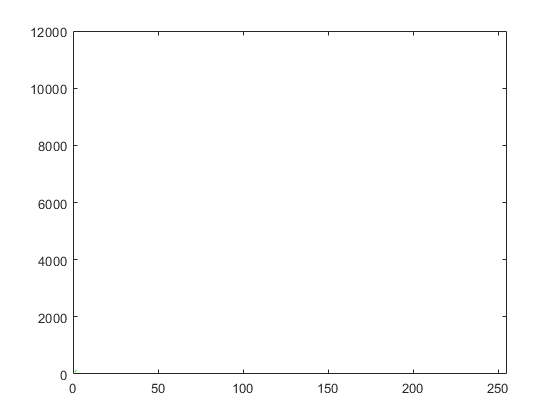

seuil = 1×2
     1   255


     1143538        2337
        2337      944846



       Contrast: 0.0022
    Correlation: 0.9955
         Energy: 0.5023
    Homogeneity: 0.9989



final = [];
j = 1;

%loop through the images
while(hasdata(breastImds))
    I = read(breastImds);
    img_seg = segmenta(I);
    
    
    [GLCM, SI] = graycomatrix(img_seg,'Offset',[1 1],'NumLevels',2,'GrayLimits',[],'Symmetric', true);
    stats = graycoprops(GLCM,'all');
    disp(GLCM);
    disp(stats);
    cell = struct2cell(stats);
    flipCell = transpose(cell);
    rowToAdd = [flipCell condition(j,1)];
    adding = [final;rowToAdd];
    final = adding;
    j = j+1;
end


Table = table(final);
filename = 'results_extra.xlsx';
writetable(Table,filename,'Sheet',1,'Range','B3');
finalTable = readtable(filename);
finalTable.Properties.VariableNames{'final_1'} = 'Contrast';
finalTable.Properties.VariableNames{'final_2'} = 'Correlation';
finalTable.Properties.VariableNames{'final_3'} = 'Energy';
finalTable.Properties.VariableNames{'final_4'} = 'Homogeneity';
finalTable.Properties.VariableNames{'final_5'} = 'Actual Condition';
writetable(finalTable,filename,'Sheet',1,'Range','B3');